# Initialization

units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
% add_Li = aLi_12*0.6;
add_Li = 2526*a0;
omegax = 16*pi*2; % trap frequencies 
omegay = 74*pi*2;
omegaz = 68*pi*2;

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;
CrossingAngle = 15/180*pi; % cross angle for two ODT beams
D = Wavelength/(2*sin(CrossingAngle/2)); % Lattice period 4 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 250 Hz.

LatticePotential = 50; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 ); % function representing the external potential (must have 3 arguments)


xmax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
N = 1000; % number of grid points for coordinate grid


useGPU = false;

if gpuDeviceCount>0 && useGPU
    x = gpuArray.linspace(-xmax,xmax,N);
    y = gpuArray.linspace(-xmax,xmax,N);
    grid = grid1d(x);
    a = gpuDevice;
    fprintf('GPU is burning now! %4.2f %% has been used',a.AvailableMemory/a.TotalMemory*100)
else
    grid = grid1d(xmax,N); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)
% task.g = 16*add_Li/(3*R(2)*R(3)); % nonlinear interaction constant


task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;

## Stationary state calculation


% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);
task.g = 16*pi*add_Li/(3*rscale* R(2).*R(3)); % nonlinear interaction constant

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step

## switch on lattice for Deltat

Deltat = 600*10^-6/tscale; % total duration for simulation; (600 mico-seconds)
tstep = 20*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

NmaxP = 2; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 

task.UpdatePotential(Vlattice);
task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis(false,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int

steps_ext = 3.0000e+03


% start simulation
task.solve_split(tstep,steps_int,steps_ext); % run the calculation

Split-step: iter - 2999, mu - 471.518, calc. time - 90.613 sec.; 0 mode Proportion: 0.0352


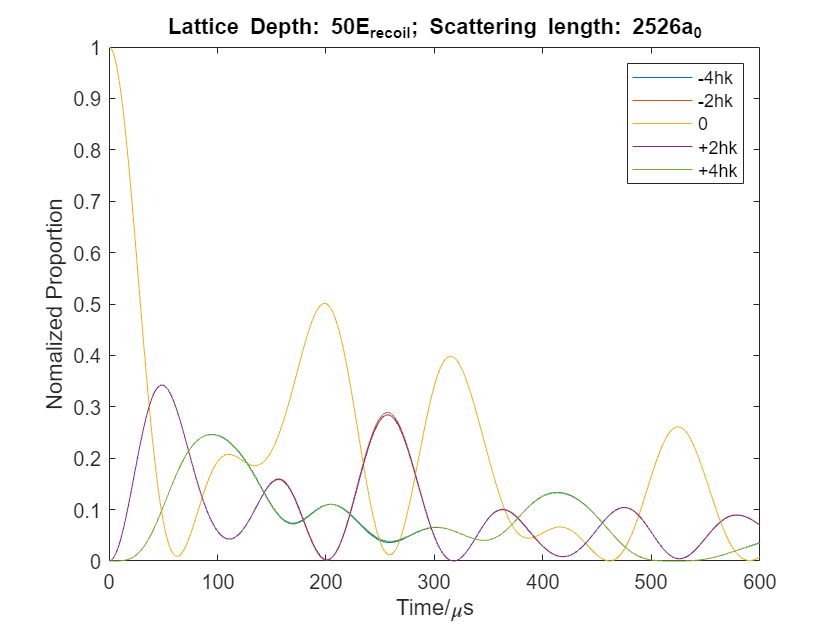

trange = (1:steps_ext)*tstep*steps_int*tscale;
task.history.MomentumDensity = task.history.MomentumDensity./max(task.history.MomentumDensity(:));
plot(trange*10^6, task.history.MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}; ' ...
    'Scattering length: ',num2str(add_Li/a0),'a_0'])
legend('-4hk','-2hk','0','+2hk','+4hk')

## simulate the potential with different interactions 500Er LatticeTime = 3\mus

a_initial =486* a0;
task.UpdatePotential(V);
[phi,mu,R] = task.groundstate_tf_harmonic(a_initial,omegax,omegay,omegaz);
task.init_state = phi;

for add = [486,(1000:1000:4000)]*a0
    % Update the task 
    LatticePotential = 500; % lattice depth in unit of recoil energy
    
    task.reInitialize

    Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
    task.UpdatePotential(Vlattice);
    
    task.g = 16*pi*a_initial/(3*rscale* R(2).*R(3)); % nonlinear interaction constant 
    task.history.MomentumDensity = [];


    Deltat = 3*10^-6/tscale; % total duration for simulation; (3 micro-seconds)
    tstep = 2*10^-9/tscale; % time step for calculation; (2 ns)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    
    % time of flight
    VToF = @(X,Y,Z) 0; 
    task.UpdatePotential(VToF);

%     TOF
    Deltat = 2*10^-6/tscale; % total duration for simulation; (2 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

% Enable the interaction
    Deltat = 10*10^-6/tscale; % total duration for simulation; (10 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.g = 16*pi*add/(3*rscale* R(2).*R(3)); % nonlinear interaction constant
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation


%     normalized the momentum density
    task.history.MomentumDensity = task.history.MomentumDensity ...
        ./max(task.history.MomentumDensity(:));
    
    trange = (1:steps_ext)*tstep*steps_int*tscale;
    plot(trange*10^6, task.history.MomentumDensity(:,NmaxP+1)' ...
        ,'DisplayName',[num2str(add/a0),'a_0'])
    hold on 

end

Split-step: iter - 150, mu - 3918.293, calc. time - 4.312 sec.; 0 mode Proportion: 0.467


Split-step: iter - 250, mu - 65.985, calc. time - 2.871 sec.; 0 mode Proportion: 0.468


Split-step: iter - 749, mu - 66.198, calc. time - 14.282 sec.; 0 mode Proportion: 0.469


Split-step: iter - 150, mu - 3918.293, calc. time - 4.289 sec.; 0 mode Proportion: 0.467


Split-step: iter - 250, mu - 65.985, calc. time - 2.833 sec.; 0 mode Proportion: 0.468


Split-step: iter - 749, mu - 90.368, calc. time - 14.291 sec.; 0 mode Proportion: 0.471


Split-step: iter - 150, mu - 3918.293, calc. time - 4.420 sec.; 0 mode Proportion: 0.467


Split-step: iter - 250, mu - 65.985, calc. time - 2.941 sec.; 0 mode Proportion: 0.468


Split-step: iter - 749, mu - 137.387, calc. time - 14.032 sec.; 0 mode Proportion: 0.475


Split-step: iter - 150, mu - 3918.293, calc. time - 4.039 sec.; 0 mode Proportion: 0.467


Split-step: iter - 250, mu - 65.985, calc. time - 2.700 sec.; 0 mode Proportion: 0.468


Split-step: iter - 749, mu - 184.402, calc. time - 13.453 sec.; 0 mode Proportion: 0.478


Split-step: iter - 150, mu - 3918.293, calc. time - 4.038 sec.; 0 mode Proportion: 0.467


Split-step: iter - 250, mu - 65.985, calc. time - 2.695 sec.; 0 mode Proportion: 0.468


Split-step: iter - 749, mu - 231.415, calc. time - 13.436 sec.; 0 mode Proportion: 0.482


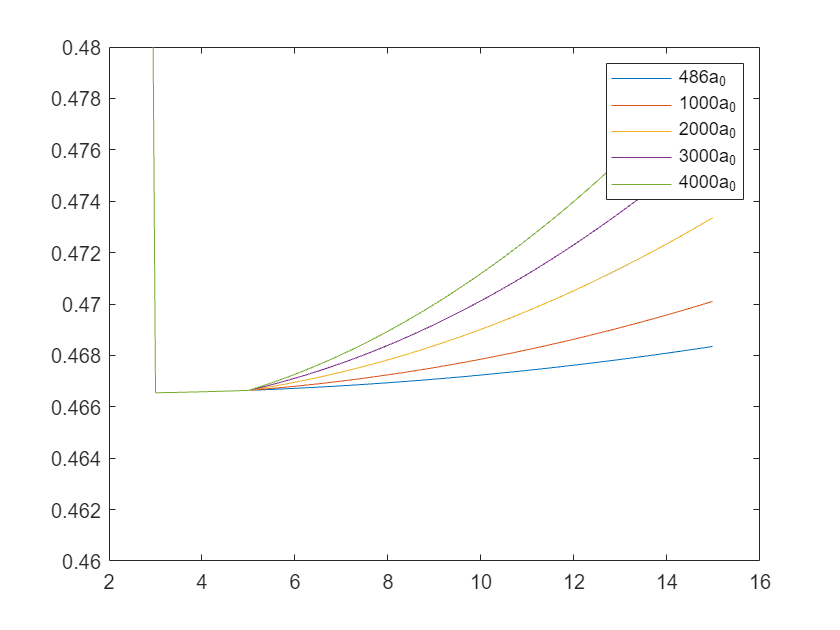

hold off
legend
ylim([0.46 0.48])

## simulate the potential with different interactions 500Er LatticeTime = 8\mus

a_initial = 486*a0;
task.UpdatePotential(V);
[phi,mu,R] = task.groundstate_tf_harmonic(a_initial,omegax,omegay,omegaz);
task.init_state = phi;

for add = [486,(1000:1000:4000)]*a0
    % Update the task 
    LatticePotential = 500; % lattice depth in unit of recoil energy
    
    task.reInitialize

    Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
    task.UpdatePotential(Vlattice);
    
    task.g = 16*pi*a_initial/(3*rscale* R(2).*R(3)); % nonlinear interaction constant 
    task.history.MomentumDensity = [];


    Deltat = 8*10^-6/tscale; % total duration for simulation; (8 micro-seconds)
    tstep = 2*10^-9/tscale; % time step for calculation; (2 ns)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    
    % time of flight
    VToF = @(X,Y,Z) 0; 
    task.UpdatePotential(VToF);

%     TOF
    Deltat = 2*10^-6/tscale; % total duration for simulation; (2 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.g = 16*pi*add/(3*rscale* R(2).*R(3)); % nonlinear interaction constant
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

% Enable the interaction
    Deltat = 10*10^-6/tscale; % total duration for simulation; (10 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.g = 16*pi*add/(3*rscale* R(2).*R(3)); % nonlinear interaction constant
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation


%     normalized the momentum density
    task.history.MomentumDensity = task.history.MomentumDensity ...
        ./max(task.history.MomentumDensity(:));
    
    trange = (1:steps_ext)*tstep*steps_int*tscale;
    plot(trange*10^6, task.history.MomentumDensity(:,NmaxP+1)' ...
        ,'DisplayName',[num2str(add/a0),'a_0'])
    hold on 

end

Split-step: iter - 399, mu - 3918.431, calc. time - 10.673 sec.; 0 mode Proportion: 0.123


Split-step: iter - 499, mu - 327.653, calc. time - 2.673 sec.; 0 mode Proportion: 0.123


Split-step: iter - 998, mu - 330.237, calc. time - 13.380 sec.; 0 mode Proportion: 0.12


Split-step: iter - 399, mu - 3918.431, calc. time - 10.692 sec.; 0 mode Proportion: 0.123


Split-step: iter - 499, mu - 352.053, calc. time - 2.685 sec.; 0 mode Proportion: 0.123


Split-step: iter - 998, mu - 357.335, calc. time - 13.347 sec.; 0 mode Proportion: 0.117


Split-step: iter - 399, mu - 3918.431, calc. time - 10.681 sec.; 0 mode Proportion: 0.123


Split-step: iter - 499, mu - 399.524, calc. time - 2.680 sec.; 0 mode Proportion: 0.122


Split-step: iter - 998, mu - 409.958, calc. time - 13.364 sec.; 0 mode Proportion: 0.112


Split-step: iter - 399, mu - 3918.431, calc. time - 10.697 sec.; 0 mode Proportion: 0.123


Split-step: iter - 499, mu - 446.994, calc. time - 2.686 sec.; 0 mode Proportion: 0.122


Split-step: iter - 998, mu - 462.457, calc. time - 13.384 sec.; 0 mode Proportion: 0.106


Split-step: iter - 399, mu - 3918.431, calc. time - 10.693 sec.; 0 mode Proportion: 0.123


Split-step: iter - 499, mu - 494.464, calc. time - 2.682 sec.; 0 mode Proportion: 0.121


Split-step: iter - 998, mu - 514.836, calc. time - 13.366 sec.; 0 mode Proportion: 0.1


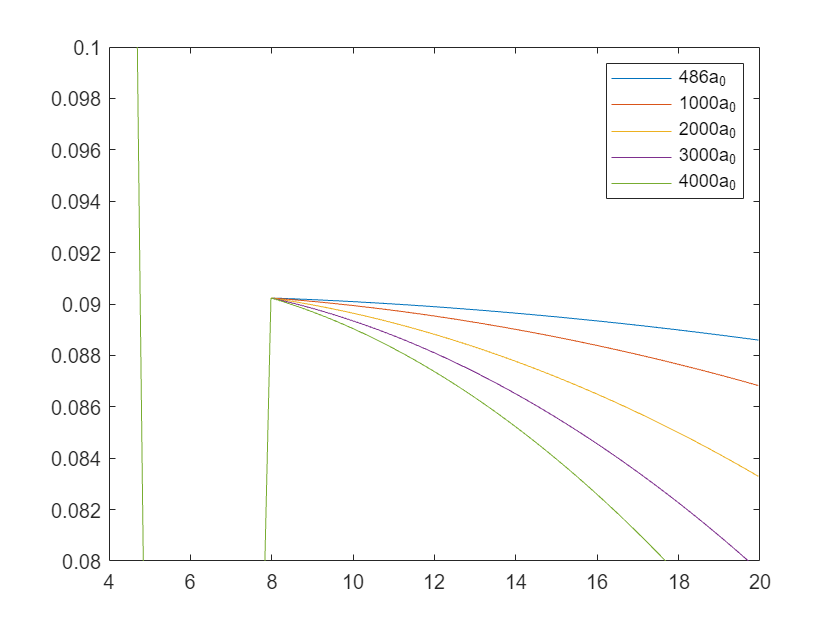

hold off
legend
ylim([0.08 0.1])

## simulate the potential with different interactions 50Er LatticeTime = 8\mus

FifthPeakLoc = [];
add_list = [1,(500:500:2500)]*a0;
for add = add_list
    % Update the task 
    LatticePotential = 50; % lattice depth in unit of recoil energy
    task.UpdatePotential(V);
    [phi,mu,R] = task.groundstate_tf_harmonic(add,omegax,omegay,omegaz);
    task.init_state = phi;
    
    Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
    task.UpdatePotential(Vlattice);
    
    task.reInitialize
    
    task.g = 16*pi*add/(3*rscale* R(2).*R(3)); % nonlinear interaction constant 
%     task.g = 2*omegay/omegax * add/rscale   ; % nonlinear interaction constant 
%     task.g/g
    task.history.MomentumDensity = [];
    
    Deltat = 800*10^-6/tscale; % total duration for simulation; (800 micro-seconds)
    tstep = 200*10^-9/tscale; % time step for calculation; (20 ns)
    steps_int = 10;
    NmaxP = 2;
    steps_ext = task.current_iter + Deltat/tstep/steps_int
    

    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    

    task.history.MomentumDensity = task.history.MomentumDensity ...
        ./max(task.history.MomentumDensity(:));
    task.history.MomentumDensity = task.history.MomentumDensity...
        ./ sum(task.history.MomentumDensity,2);
    trange = (1:steps_ext)*tstep*steps_int*tscale;

    plot(trange*10^6, task.history.MomentumDensity(:,NmaxP+1)' ...
        ,'DisplayName',[num2str(add/a0),'a_0'])
    hold on 
    [~,peakLoc] = findpeaks( task.history.MomentumDensity(:,NmaxP+1)');

    FifthPeakLoc = [FifthPeakLoc,trange(peakLoc(5))];
    task.saveTask('_U0',num2str(LatticePotential)...
                    ,'_add',num2str(add/a0));
end

steps_ext = 400.0000

Split-step: iter - 399, mu - 396.605, calc. time - 0.816 sec.; 0 mode Proportion: 0.541


steps_ext = 400.0000

Split-step: iter - 399, mu - 417.190, calc. time - 0.741 sec.; 0 mode Proportion: 0.658


steps_ext = 400.0000

Split-step: iter - 399, mu - 427.150, calc. time - 0.848 sec.; 0 mode Proportion: 0.435


steps_ext = 400.0000

Split-step: iter - 399, mu - 433.308, calc. time - 1.394 sec.; 0 mode Proportion: 0.254


steps_ext = 400.0000

Split-step: iter - 399, mu - 439.142, calc. time - 0.663 sec.; 0 mode Proportion: 0.133


steps_ext = 400.0000

Split-step: iter - 399, mu - 444.055, calc. time - 0.680 sec.; 0 mode Proportion: 0.0583


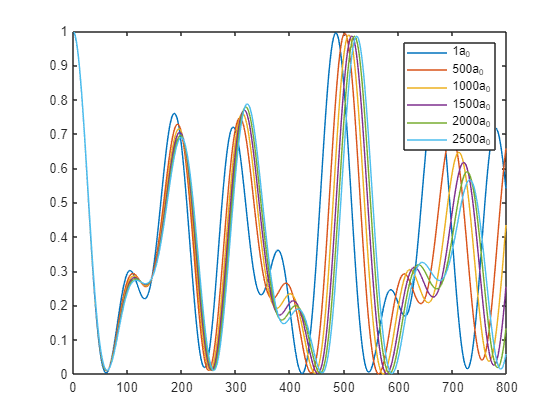

hold off
legend

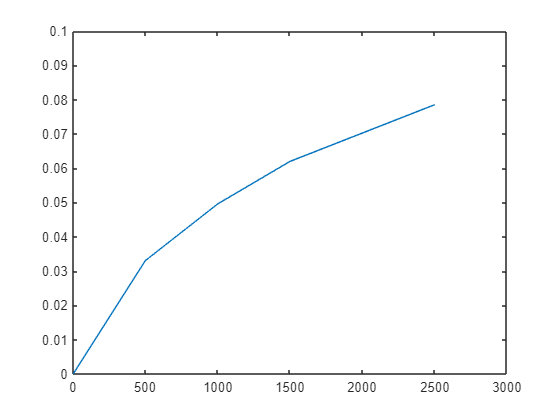


rSlowingPara = FifthPeakLoc/FifthPeakLoc(1)-1;
plot(add_list/a0,rSlowingPara);
xlim([0 3000])
ylim([0 0.1])

Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 8.8709